addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
ImageNames={'baby.png';'bird.png';'woman.png';'monarch.png';'airplane.png';'arctichare.png';'peppers1.tiff';'peppers2.png';'foreman.png'};
%ImageNames={'kodim03.png';'kodim04.png';'kodim05.png';'kodim06.png';'kodim07.png';'kodim08.png';'kodim09.png';'kodim10.png';'kodim11.png';'kodim12.png';'kodim13.png';'kodim14.png';'kodim15.png'};
%ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'aerial9.tiff';'aerial10.tiff'};
PSNR_R=zeros(size(ImageNames,1),1);
PSNR_G=zeros(size(ImageNames,1),1);
PSNR_B=zeros(size(ImageNames,1),1);
SSIM_R=zeros(size(ImageNames,1),1);
SSIM_G=zeros(size(ImageNames,1),1);
SSIM_B=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=imread(string);
    %A=imgaussfilt(A,0.1);
    R = double(A(:,:,1)); % Red channel
    G = double(A(:,:,2)); % Green channel
    B = double(A(:,:,3)); % Blue channel
    [SR3,SR3G,SR3B]= KipkoechSuperResolution (R,G,B);
    SRimage=cat(3,uint8(SR3),uint8(SR3G),uint8(SR3B));
    [k,j]=size(SR3);
    R=imresize(R,[k j]);
    G=imresize(G,[k j]);
    B=imresize(B,[k j]);
    imagee=cat(3,uint8(SR3),uint8(SR3G),uint8(SR3B));
    PSNR_R(i)=psnr(uint8(SR3),uint8(R));
    PSNR_G(i)=psnr(uint8(SR3G),uint8(G));
    PSNR_B(i)=psnr(uint8(SR3B),uint8(B));
    SSIM_R(i)=ssim(uint8(SR3),uint8(R));
    SSIM_G(i)=ssim(uint8(SR3G),uint8(G));
    SSIM_B(i)=ssim(uint8(SR3B),uint8(B));
end
toc

Elapsed time is 4.651497 seconds.


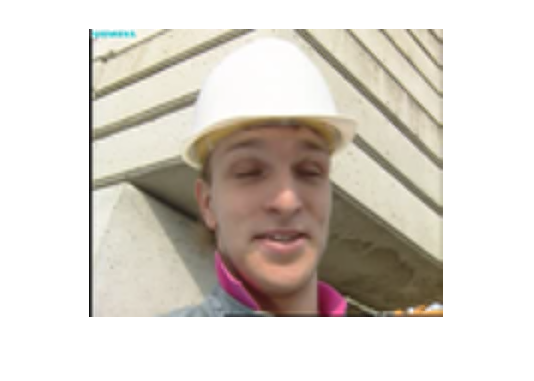

imshow(imagee)

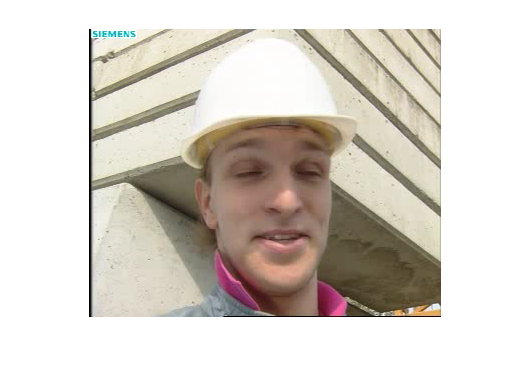

imshow(A)

%imwrite(imagee,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\resultsfactor3\Peppers1Proposed.png')

T=table(ImageNames,PSNR_R,PSNR_G,PSNR_B,SSIM_R,SSIM_G,SSIM_B)

T = 9×7 table
        ImageNames        PSNR_R    PSNR_G    PSNR_B    SSIM_R     SSIM_G     SSIM_B 
    __________________    ______    ______    ______    _______    _______    _______

    {'baby.png'      }     30.53    31.038      31.3     0.8837    0.88295    0.86088
    {'bird.png'      }    30.337    30.816    30.768    0.91401     0.9126    0.89549
    {'woman.png'     }    26.845    26.867    26.896    0.86585    0.87272    0.87004
    {'monarch.png'   }    27.523    27.385     27.85    0.90931    0.90477    0.89275
    {'airplane.png'  }    26.981    25.799    28.578    0.86318    0.85272    0.86073
    {'arctichare.png'}    29.549    32.162    33.341    0.90824    0.92038     0.9261
    {'peppers1.tiff' }    29.221    26.406    29.058     0.

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\FinalColourImagesMagnification3g.xlsx'];
writetable(T,path_format)

function [SR3,SR3G,SR3B]= KipkoechSuperResolution(R,G,B)
k=3;
LR=KipkoechDownSampling(R,k);
LRG=KipkoechDownSampling(G,k);
LRB=KipkoechDownSampling(B,k);
LRPrefiltered=KipkoechCubicBSplinesPrefilter(LR);
LRGPrefiltered=KipkoechCubicBSplinesPrefilter(LRG);
LRBPrefiltered=KipkoechCubicBSplinesPrefilter(LRB);
InterpolatedImageR=KipkoechBSplinesInterpolation(LRPrefiltered,k);
InterpolatedImageG=KipkoechBSplinesInterpolation(LRGPrefiltered,k);
InterpolatedImageB=KipkoechBSplinesInterpolation(LRBPrefiltered,k);
[~,LH,HL,HH]=dwt2(InterpolatedImageR,'db1'); %DWT Decomposition of LR
[~,LHG,HLG,HHG]=dwt2(InterpolatedImageG,'db1');
[~,LHB,HLB,HHB]=dwt2(InterpolatedImageB,'db1');
[m,n]=size(LH);
LR=imresize(LR,[m n]);
LRG=imresize(LRG,[m n]);
LRB=imresize(LRB,[m n]);
SRInitial=idwt2(LR.*2,LH,HL,HH,'db1');
SRInitialG=idwt2(LRG.*2,LHG,HLG,HHG,'db1');
SRInitialB=idwt2(LRB.*2,LHB,HLB,HHB,'db1');
% Downsample SR
LR1=imresize(SRInitial,[m n]);
LR1G=imresize(SRInitialG,[m n]);
LR1B=imresize(SRInitialB,[m n]);
[M,N]=size(LR1);
HF=zeros(M,N);
%Back Projection Step 1
E1=LR-LR1;
E1G=LRG-LR1G;
E1B=LRB-LR1B;
E1i=weightedguidedfilter(E1,E1,9,0.001);
E1iG=weightedguidedfilter(E1G,E1G,9,0.001);
E1iB=weightedguidedfilter(E1B,E1B,9,0.001);
E11=double(E1i).*2;
E11G=double(E1iG).*2;
E11B=double(E1iB).*2;
BP1=idwt2(E11,HF,HF,HF,'db1');
BP1G=idwt2(E11G,HF,HF,HF,'db1');
BP1B=idwt2(E11B,HF,HF,HF,'db1');
SR1=SRInitial+BP1;
SR1G=SRInitialG+BP1G;
SR1B=SRInitialB+BP1B;
% Back Projection Step 2
LR2=imresize(SR1,[m n]);
LR2G=imresize(SR1G,[m n]);
LR2B=imresize(SR1B,[m n]);
E2=LR-LR2;
E2G=LRG-LR2G;
E2B=LRB-LR2B;
E2i=weightedguidedfilter(E2,E2,7,1);
E2iG=weightedguidedfilter(E2G,E2G,7,1);
E2iB=weightedguidedfilter(E2B,E2B,7,1);
E22=double(E2i).*2;
E22G=double(E2iG).*2;
E22B=double(E2iB).*2;
BP2=idwt2(E22,HF,HF,HF,'db1');
BP2G=idwt2(E22G,HF,HF,HF,'db1');
BP2B=idwt2(E22B,HF,HF,HF,'db1');
SR2=SR1+BP2;
SR2G=SR1G+BP2G;
SR2B=SR1B+BP2B;
% Back Projection Step 3
LR3=imresize(SR2,[m n]);
LR3G=imresize(SR2G,[m n]);
LR3B=imresize(SR2B,[m n]);
E3=LR-LR3;
E3G=LRG-LR3G;
E3B=LRB-LR3B;
E3i=weightedguidedfilter(E3,E3,7,1);
E3iG=weightedguidedfilter(E3G,E3G,7,1);
E3iB=weightedguidedfilter(E3B,E3B,7,1);
E33=double(E3i).*2;
E33G=double(E3iG).*2;
E33B=double(E3iB).*2;
BP3=idwt2(E33,HF,HF,HF,'db1');
BP3G=idwt2(E33G,HF,HF,HF,'db1');
BP3B=idwt2(E33B,HF,HF,HF,'db1');
SR3=SR2+BP3;
SR3G=SR2G+BP3G;
SR3B=SR2B+BP3B;
end
